mydata = load('RSdata.mat')

mydata = struct with fields:
            rt_tout: [1600×1 double]
      rt_ScopeData4: [1×1 struct]
    rt_motor_speeds: [1×1 struct]
               rt_u: [1×1 struct]
               rt_v: [1×1 struct]
               rt_w: [1×1 struct]
        rt_pressure: [1×1 struct]
    rt_z_ultrasonic: [1×1 struct]
             rt_a_x: [1×1 struct]
             rt_a_y: [1×1 struct]
             rt_a_z: [1×1 struct]
               rt_p: [1×1 struct]
               rt_q: [1×1 struct]
               rt_r: [1×1 struct]



%ms = mydata.rt_motor_speeds.signals.values;

% u = mydata.rt_optical_flow.signals.values(:,1);
% v = mydata.rt_optical_flow.signals.values(:,2);
% w = mydata.rt_optical_flow.signals.values(:,3);
u = mydata.rt_u.signals.values;
v = mydata.rt_v.signals.values;
w = mydata.rt_w.signals.values;
a_x = mydata.rt_a_x.signals.values;
a_y = mydata.rt_a_y.signals.values;
a_z = mydata.rt_a_z.signals.values;
p = mydata.rt_p.signals.values;
q = mydata.rt_q.signals.values;
r = mydata.rt_r.signals.values;
p_0 = mydata.rt_pressure.signals.values;
z_us = mydata.rt_z_ultrasonic.signals.values;

all_data = [u, v, a_x, a_y, a_z, p, q, r, p_0, z_us];
labels = ["u", "v", "a_x", "a_y", "a_z", "p", "q", "r", "p_0","z_us"];

u_mean = mean(u)

u_mean = single
-0.0013

u_cov = cov(u)

u_cov = single
0.0042

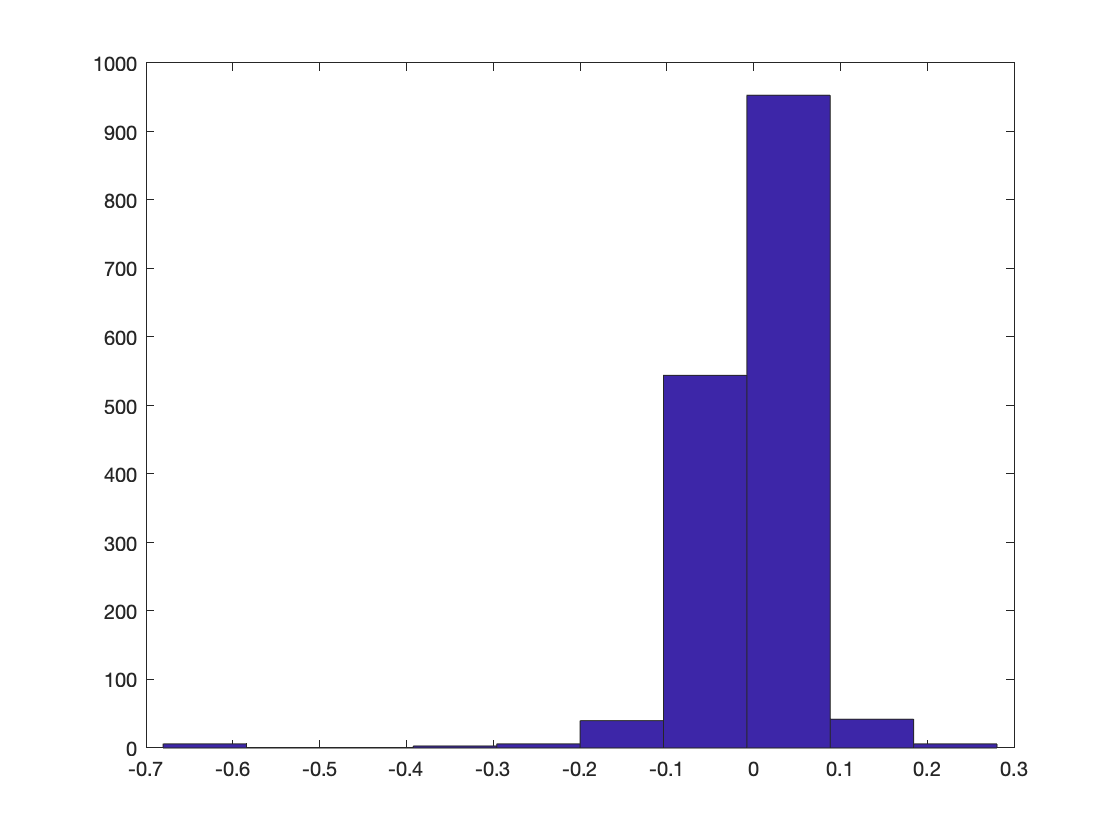

hist(u,10)


v_mean = mean(v)

v_mean = single
0.0064

v_cov = cov(v)

v_cov = single
0.0013

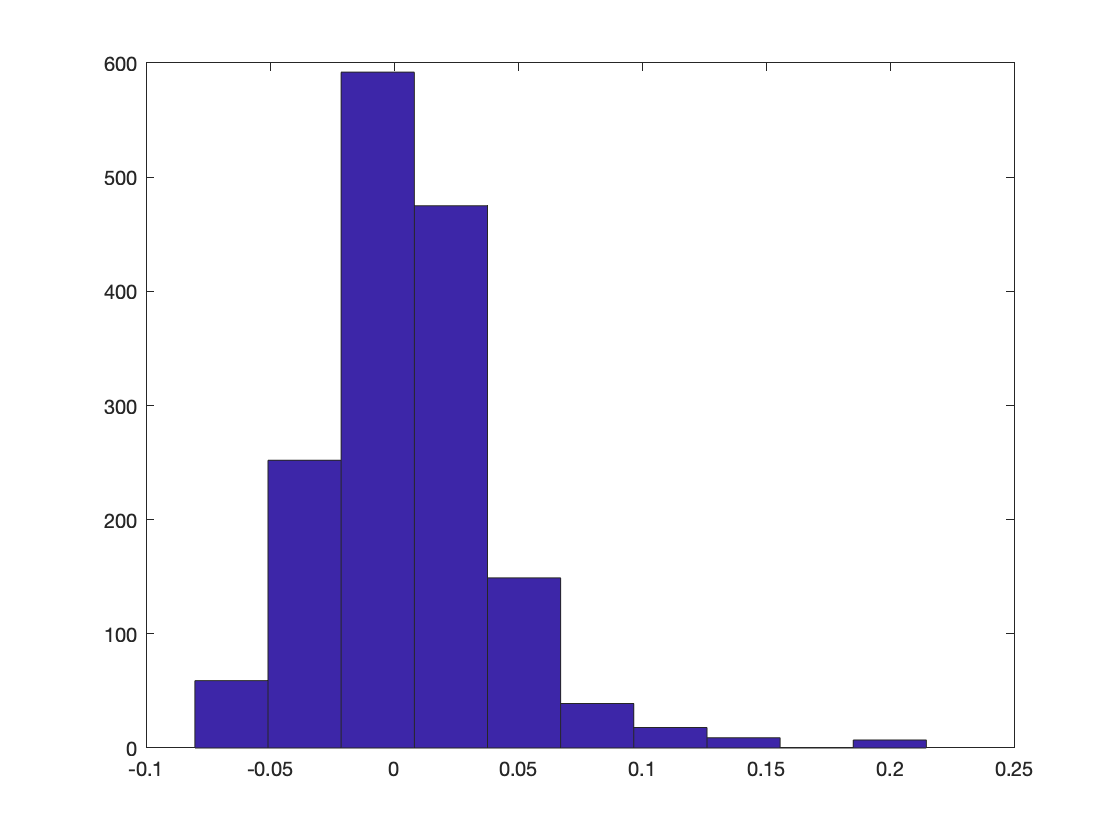

hist(v,10)


w_mean = mean(w)

w_mean = single
-0.3812

w_cov = cov(w)

w_cov = single
0.8552

hist(v,10)


a_x_mean = mean(a_x)

a_x_mean = single
-0.0508

a_x_cov = cov(a_x)

a_x_cov = single
0.1504

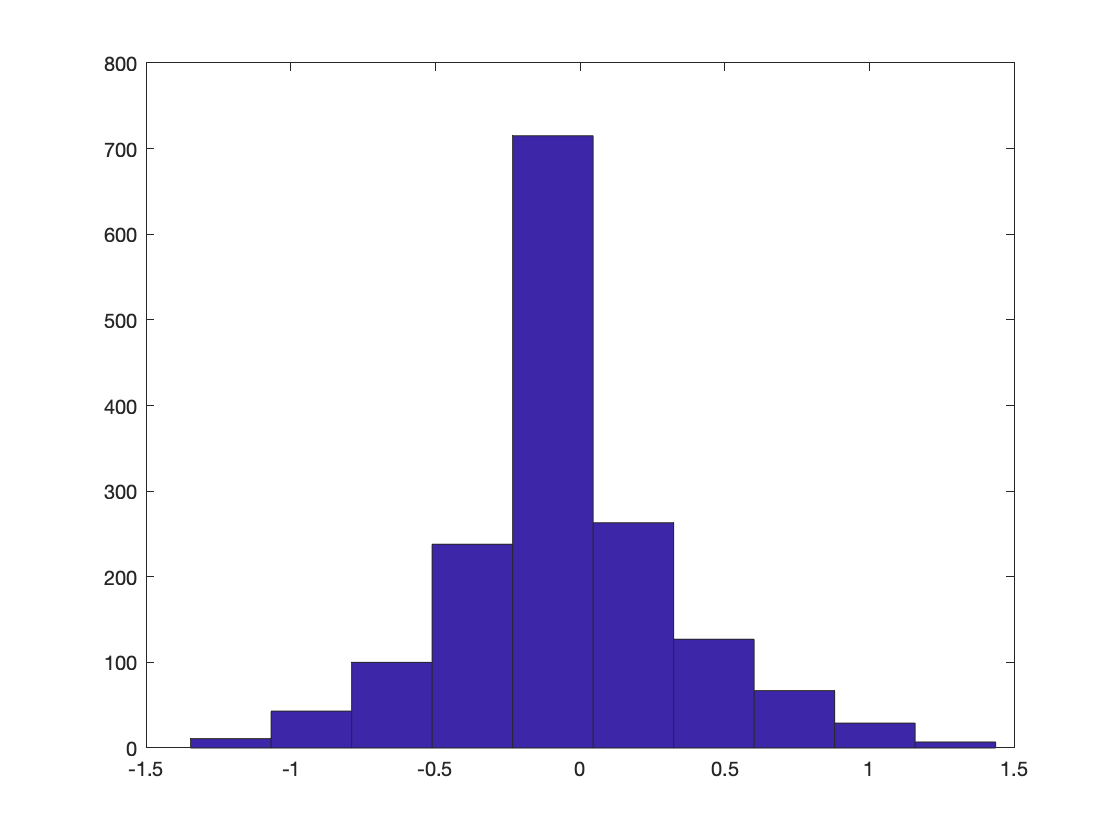

hist(a_x,10)


a_z_mean = mean(a_y)

a_z_mean = single
-0.2933

a_z_cov = cov(a_y)

a_z_cov = single
0.1215

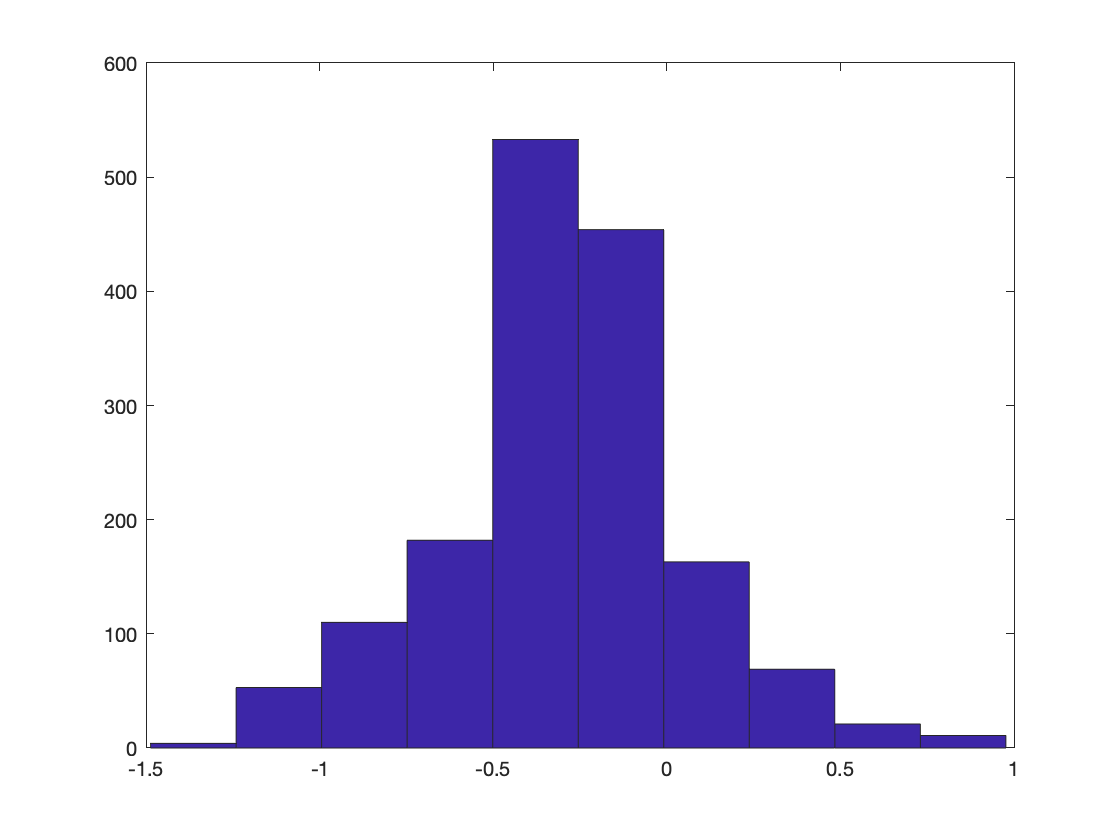

hist(a_y)


a_z_mean = mean(a_z)

a_z_mean = single
-9.1338

a_z_cov = cov(a_z)

a_z_cov = single
0.0484

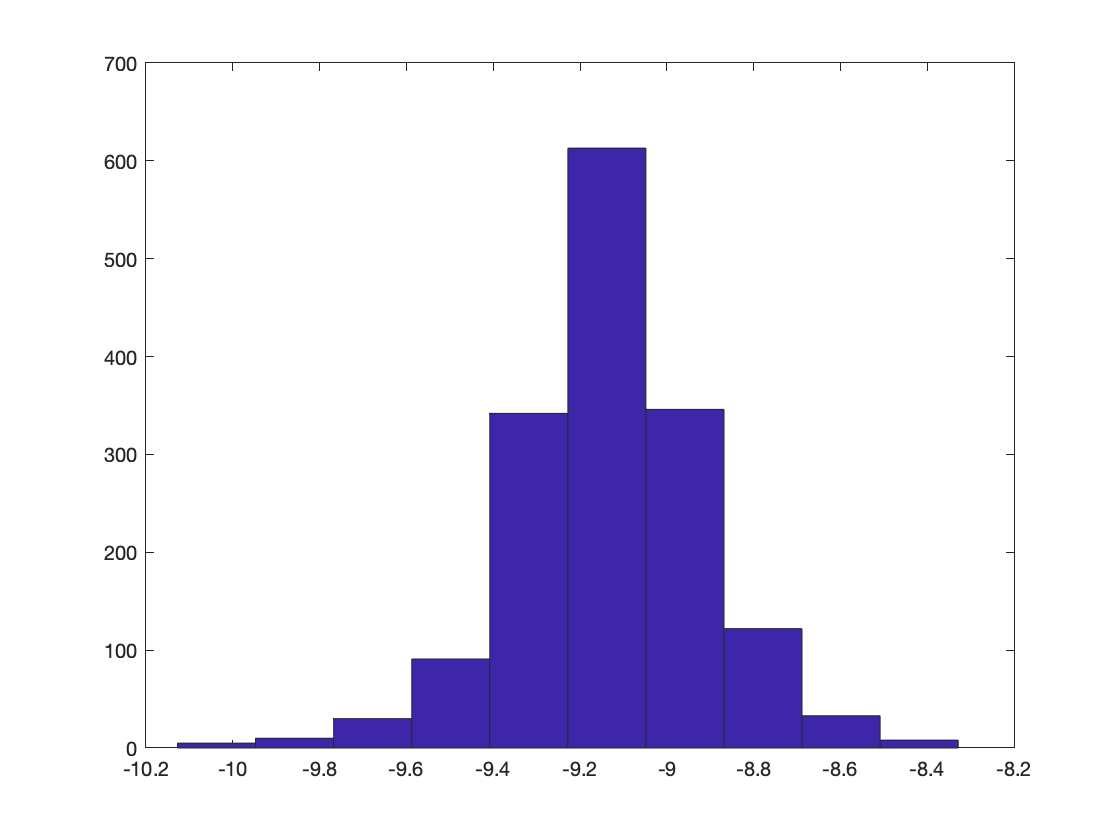

hist(a_z)


p_mean = mean(p)

p_mean = single
-0.0087

p_cov = cov(p)

p_cov = single
0.0036

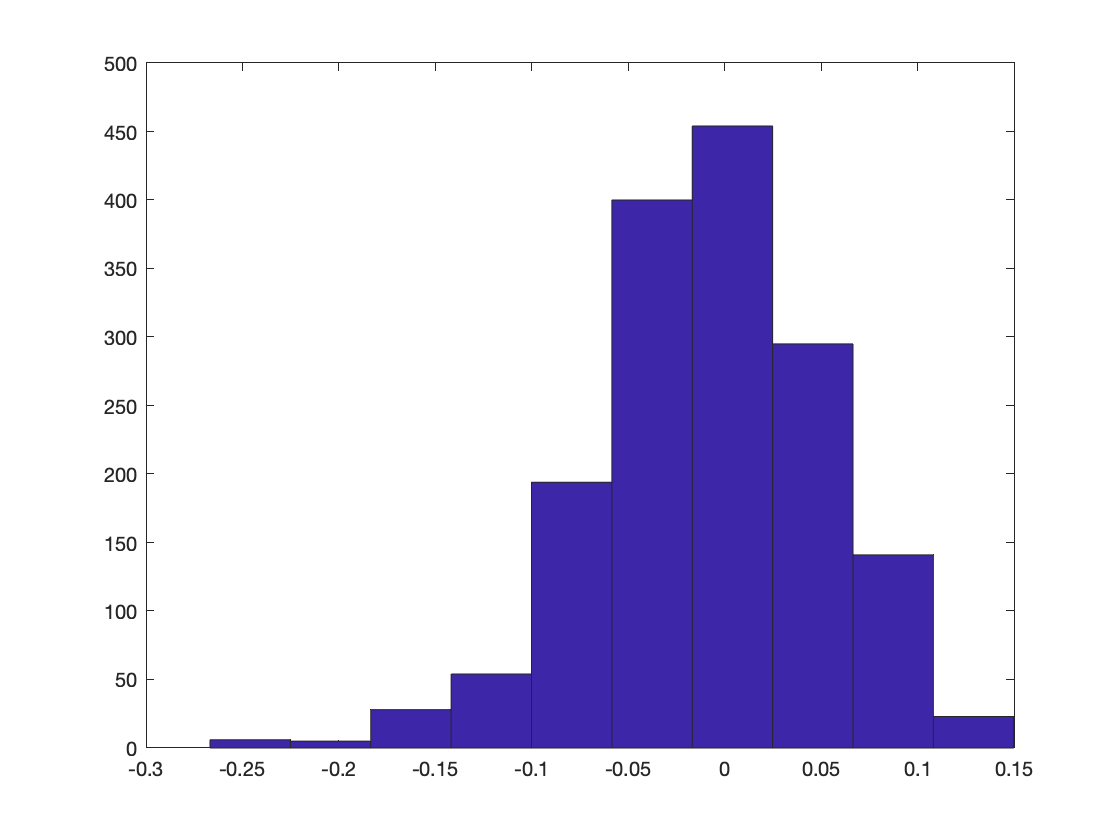

hist(p)


q_mean = mean(q)

q_mean = single
-0.0306

q_cov = cov(q)

q_cov = single
0.0104

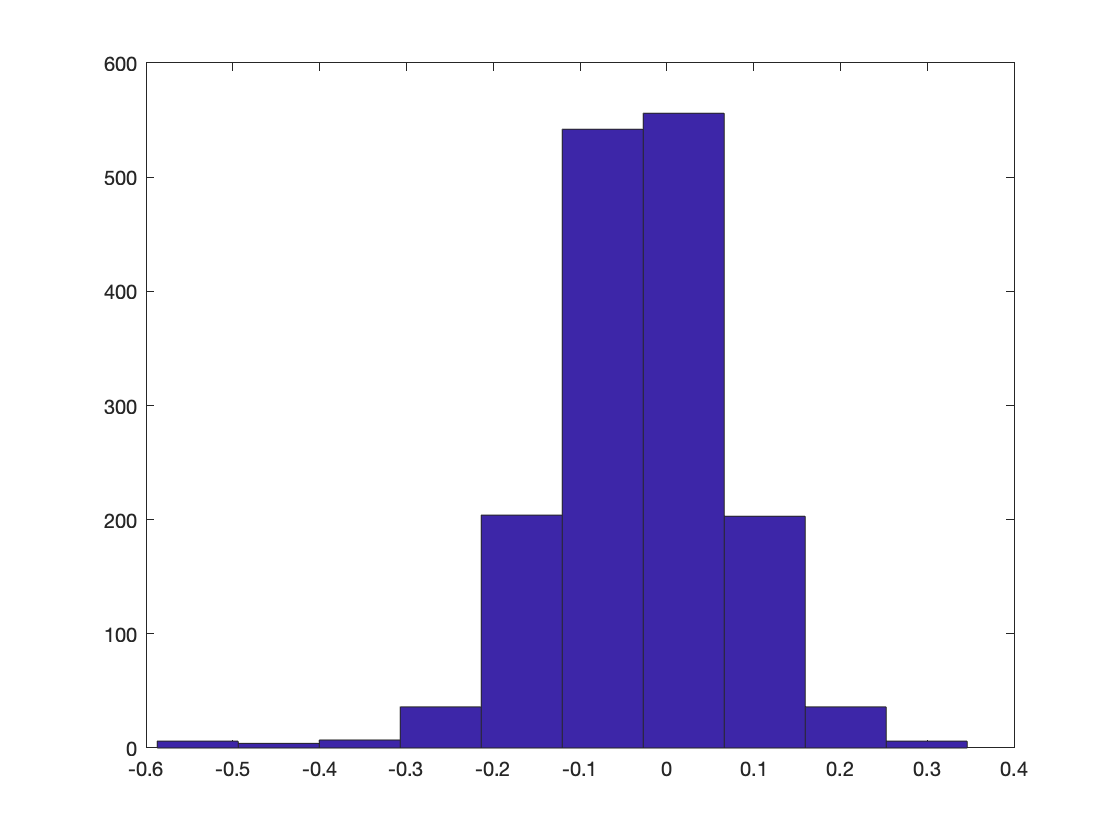

hist(q)


r_mean = mean(r)

r_mean = single
0.0096

r_cov = cov(r)

r_cov = single
0.0117

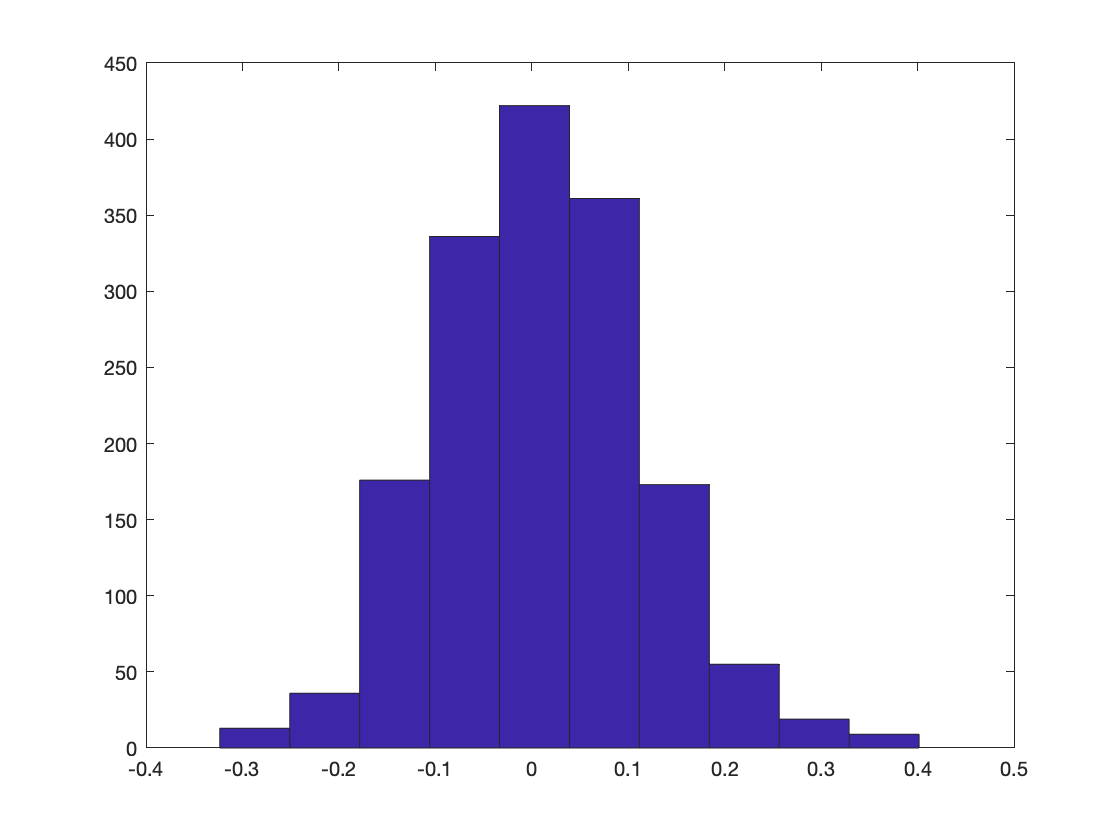

hist(r)


g = 9.8; % acceleration due to gravity m/s^2
M = 0.0289644; % molar mass of air in kg/mol
R = 8.31432; % universal gas constant Nm/mol/k
p0 = 101325 % Pa standard pressure

p0 = 101325

T =288.15;  % Assumed temperature in kelvin
K =-g*M/R/T;
dt = 1/200;
Kappa = 1;



z_hypsometric =@(P) 1/K.*log(P./p0)

z_hypsometric = function_handle with value:
    @(P)1/K.*log(P./p0)


p_0_mean = mean(p_0)

p_0_mean = single
9.9584e+04

difference = z_hypsometric(p_0) - z_hypsometric(p_0_mean)

difference = 1600×1 single column vector
   -0.7058
   -0.7017
   -0.7017
   -0.7017
   -0.9111
   -0.9111
   -0.9111
   -0.7621
   -0.7621
   -0.7621


p_cov = cov(difference) %p_0

p_cov = single
0.2022

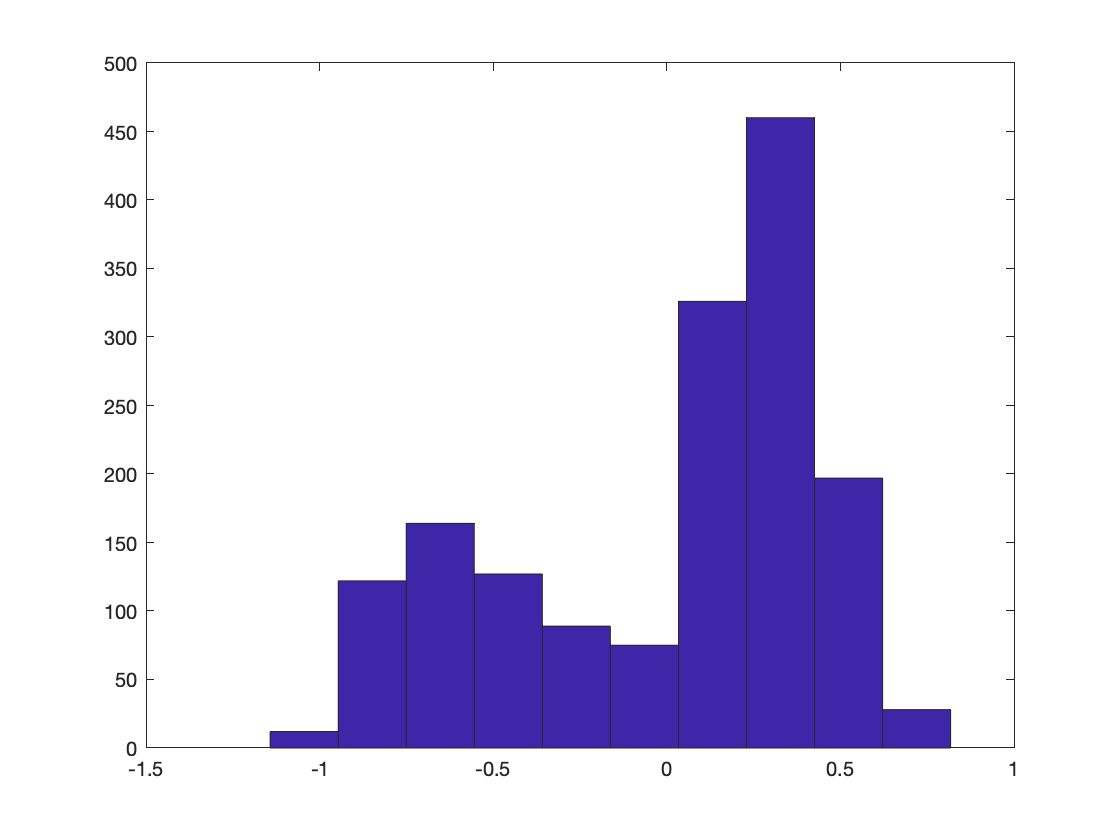

hist(difference)



z_us_mean = mean(z_us)

z_us_mean = single
0.4444

z_us_cov = cov(z_us)

z_us_cov = single
0.0018

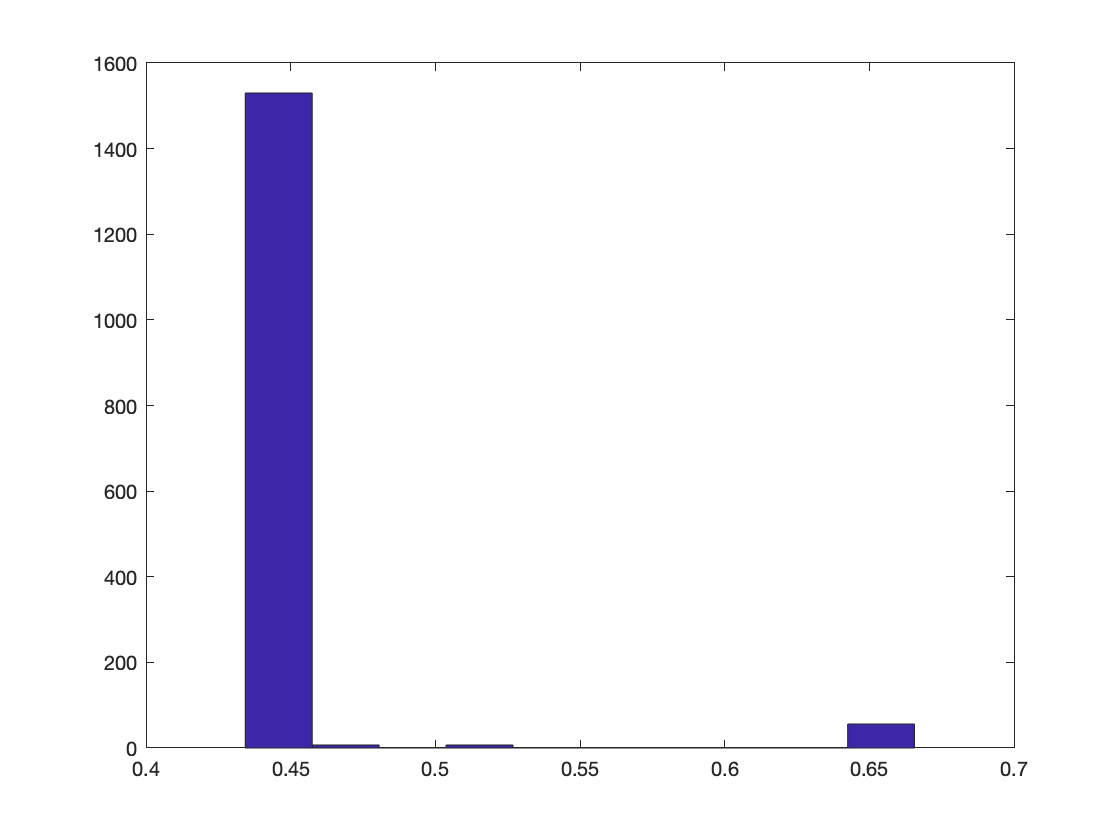

hist(z_us)


for i = 1:10
    for j = 1:10
        correlation = corr(all_data(:,i),all_data(:,j));
        if correlation > 0.3 && (i ~= j)
            fprintf('Correlation between %s and %s is %f \n',labels(i),labels(j),corr(all_data(:,i),all_data(:,j)))
        end
    end
end

Correlation between u and v is 0.375495 
Correlation between u and q is 0.379746 
Correlation between v and u is 0.375495 
Correlation between q and u is 0.379746 
Correlation between q and r is 0.347411 
Correlation between r and q is 0.347411 


corr_matrix = corrcoef(all_data)

corr_matrix = 10×10 single matrix
    1.0000    0.3755   -0.1272   -0.0154   -0.1807   -0.0850    0.3797   -0.0933   -0.0274    0.1252
    0.3755    1.0000   -0.0715   -0.2572    0.1366   -0.1108    0.2339   -0.1242    0.1061   -0.0271
   -0.1272   -0.0715    1.0000   -0.5952   -0.0657    0.0883   -0.1246    0.0325    0.1371   -0.1283
   -0.0154   -0.2572   -0.5952    1.0000   -0.0498    0.0328    0.0543   -0.0465   -0.3400    0.0609
   -0.1807    0.1366   -0.0657   -0.0498    1.0000    0.0560   -0.2140   -0.0507    0.0143   -0.2224
   -0.0850   -0.1108    0.0883    0.0328    0.0560    1.0000   -0.2700   -0.5485   -0.0978   -0.0365
    0.3797    0.2339   -0.1246    0.0543   -0.2140   -0.2700    1.0000    0.3474    0.0109    0.0292
   -0.0933   -0.1242    0.0325   -0.0465   -0.0507   -0.5485    0.3474    1.0000    0.0478   -0.0931
   -0.0274    0.1061    0.1371   -0.3400    0.0143   -0.0978    0.0109    0.0478    1.0000    0.0091
    0.1252   -0.0271   -0.1283    0.0609   -0.2224   -0.0


A_e_dis = expm(A_aileron(1:2,1:2).*dt)

A_e_dis =     1.0000    0.0479
         0    1.0000


B_e_dis = A_aileron(1:2,3).* dt; 
C_e_dis = eye(2);

A_a_dis = expm(A_elevator(1:2,1:2).*dt)

A_a_dis =     1.0000   -0.0479
         0    1.0000


B_a_dis = A_elevator(1:2,3).* dt; 
C_a_dis = eye(2);

Q_e_dis = q_cov*dt;
Q_a_dis = p_cov*dt;

theta_estimate = atan(-a_x./sqrt(a_y.^2 + a_z.^2));
phi_estimate = atan(a_y./a_z);
v_estimate = 1*z_us.*v;

R_e = cov([u theta_estimate])

R_e = 2×2 single matrix
    0.0042    0.0003
    0.0003    0.0018


R_a = cov([v phi_estimate])

R_a = 2×2 single matrix
    0.0013    0.0004
    0.0004    0.0015


%R_a = [var(v_estimate) 0; 0 var(phi_estimate)]

R_a = 2×2 single matrix
    0.0003         0
         0    0.0015


A_t_dis = expm(A_throttle.*dt);
B_t_dis = B_throttle.*dt;
C_t_dis = [1 0];

Q_t_dis = [0 0;
           0 a_z_cov*dt];
R_t = z_us_cov;

A_r_dis = expm(A_rudder.*dt);
B_r_dis = B_rudder.*dt;
C_r_dis = [1 0];

Q_r_dis = r_cov*dt

Q_r_dis = single
5.8358e-05

%R_r =;